Séance 2 - TP /Projet - MSA

Bachelard - Laleu

clear all

Nu0 = sqrt(2)/8;
N = 512;
sigmaCarre = 0.5;
a = 0.5; % coefficient du filtre AR1


Sin = SinPalea(Nu0, 2, N)

Sin =    -0.6786    1.3845    1.9080    0.3099   -1.6328   -1.7599    0.0700    1.8220    1.5480   -0.4473   -1.9453   -1.2801    0.8084    1.9981    0.9659   -1.1403   -1.9785   -0.6167    1.4309    1.8874    0.2451   -1.6697   -1.7279    0.1353    1.8480    1.5058   -0.5108   -1.9594   -1.2292    0.8678    1.9999    0.9081   -1.1934   -1.9679   -0.5542    1.4758    1.8647    0.1801   -1.7048   -1.6940    0.2004    1.8720    1.4620   -0.5737   -1.9715   -1.1770    0.9263    1.9995    0.8494   -1.2452


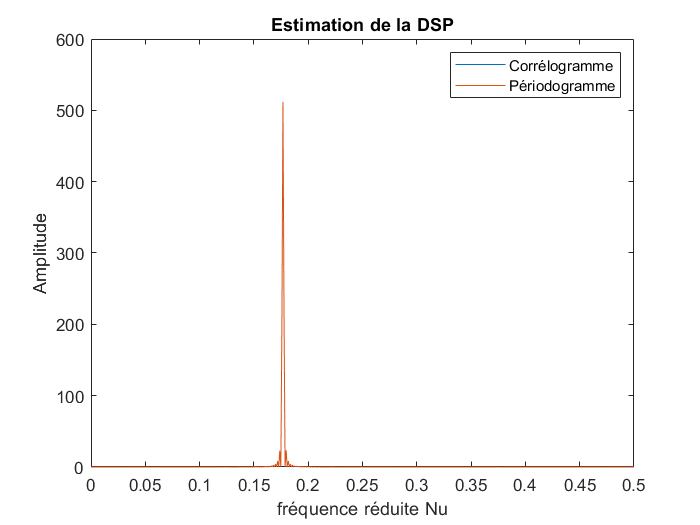


[PSDsin, Nusin] = psdEstimatorC(Sin, 1024);



plot(Nusin, PSDsin)
%xlim([0, 100])
xlabel("fréquence réduite Nu")
ylabel("Amplitude")
%title("Estimation de la DSP par Corrélogramme")

hold on

[PSDsinP, NusinP] = psdEstimatorP(Sin, 1024);

plot(Nusin, PSDsin)
%xlim([0, 100])

title("Estimation de la DSP")
legend("Corrélogramme", "Périodogramme");

hold off

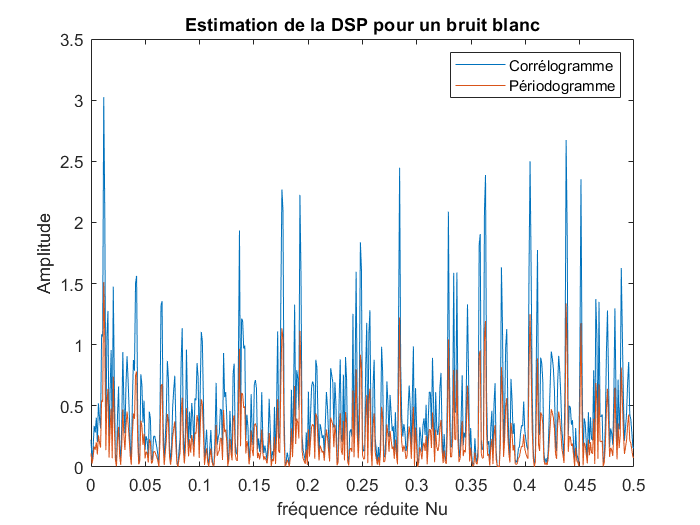



BruitB = BruitBlanc(N, sigmaCarre);

[PSDbb, Nubb] = psdEstimatorC(BruitB);
[PSDbbP, NubbP] = psdEstimatorP(BruitB);

plot(Nubb, PSDbb)
xlabel("fréquence réduite Nu")
ylabel("Amplitude")

hold on 

plot(NubbP, PSDbbP)
title("Estimation de la DSP pour un bruit blanc")
legend("Corrélogramme", "Périodogramme");

hold off


PSDbbPMoy = 0;
for i=1:257
PSDbbPMoy = PSDbbPMoy + PSDbbP(i);
end

PSDbbPMoy = PSDbbPMoy/257

PSDbbPMoy = 0.2439

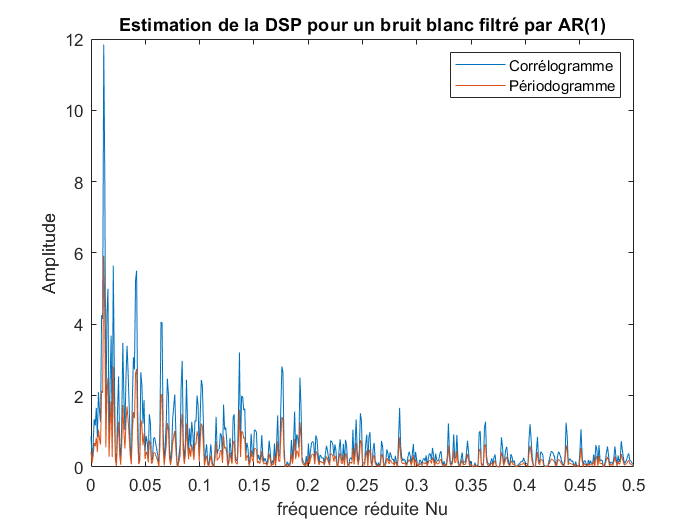



BBfiltreParAR1 = AR1(a, BruitB);


[PSDbbfiltre, Nubbfiltre] = psdEstimatorC(BBfiltreParAR1);
[PSDbbfiltreP, NubbfiltreP] = psdEstimatorP(BBfiltreParAR1);

plot(Nubbfiltre, PSDbbfiltre)
xlabel("fréquence réduite Nu")
ylabel("Amplitude")

hold on 

plot(NubbfiltreP, PSDbbfiltreP)
title("Estimation de la DSP pour un bruit blanc filtré par AR(1)")
legend("Corrélogramme", "Périodogramme");

hold off

Test par division en K portions


Sin = SinPalea(Nu0, 2, N)

Sin =     1.9663    1.2008   -0.9000   -2.0000   -0.8761    1.2220    1.9612    0.5197   -1.4998   -1.8515   -0.1444    1.7232    1.6747   -0.2360   -1.8843   -1.4373    0.6080    1.9772    1.1478   -0.9579   -1.9985   -0.8168    1.2731    1.9474    0.4562   -1.5422   -1.8258   -0.0791    1.7555    1.6381   -0.3008   -1.9052   -1.3911    0.6699    1.9860    1.0937   -1.0147   -1.9948   -0.7567    1.3228    1.9314    0.3923   -1.5830   -1.7981   -0.0138    1.7859    1.5997   -0.3653   -1.9241   -1.3433


abs(1024/3)

ans = 341.3333

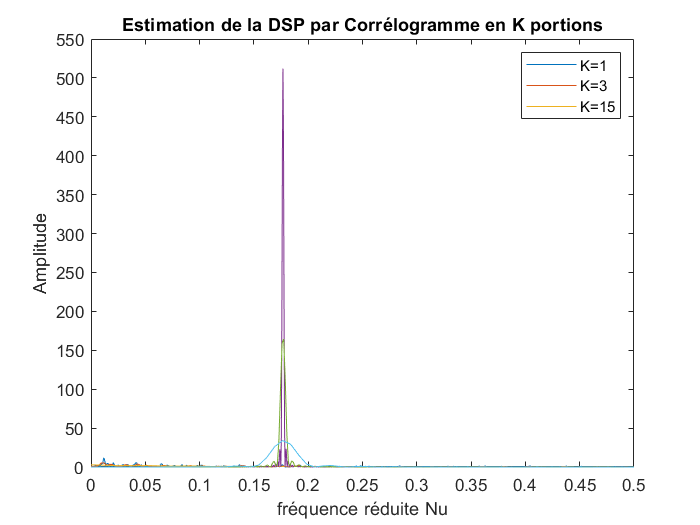


[PSDsin2, Nusin2] = psdEstimatorC2(Sin, 2048);

[PSDsin3, Nusin3] = psdEstimatorC2(Sin, 2048, 3);

[PSDsin4, Nusin4] = psdEstimatorC2(Sin, 2048, 15);

plot(Nusin2, PSDsin2)
ylim([0, 550])
xlabel("fréquence réduite Nu")
ylabel("Amplitude")
title("Estimation de la DSP par Corrélogramme en K portions")

hold on 

plot(Nusin3, PSDsin3)

plot(Nusin4, PSDsin4)

legend("K=1", "K=3", "K=15")

hold off

bblanc

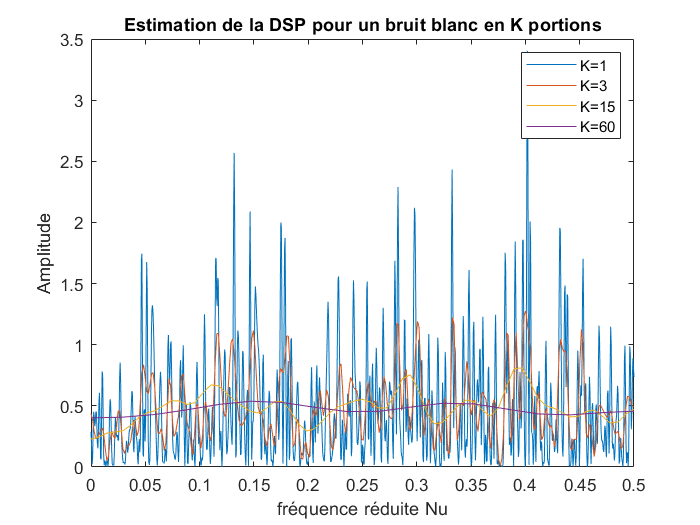

BruitB = BruitBlanc(N, sigmaCarre);

[PSDbb2, Nubb2] = psdEstimatorC2(BruitB, 2048);
[PSDbb3, Nubb3] = psdEstimatorC2(BruitB, 2048, 3 );
[PSDbb4, Nubb4] = psdEstimatorC2(BruitB, 2048, 15 );
[PSDbb5, Nubb5] = psdEstimatorC2(BruitB, 2048, 60 );


plot(Nubb2, PSDbb2)
xlabel("fréquence réduite Nu")
ylabel("Amplitude")

hold on 

plot(Nubb3, PSDbb3)
plot(Nubb4, PSDbb4)
plot(Nubb5, PSDbb5)
title("Estimation de la DSP pour un bruit blanc en K portions")
legend("K=1", "K=3", "K=15", "K=60");

hold off

bblanc filtré

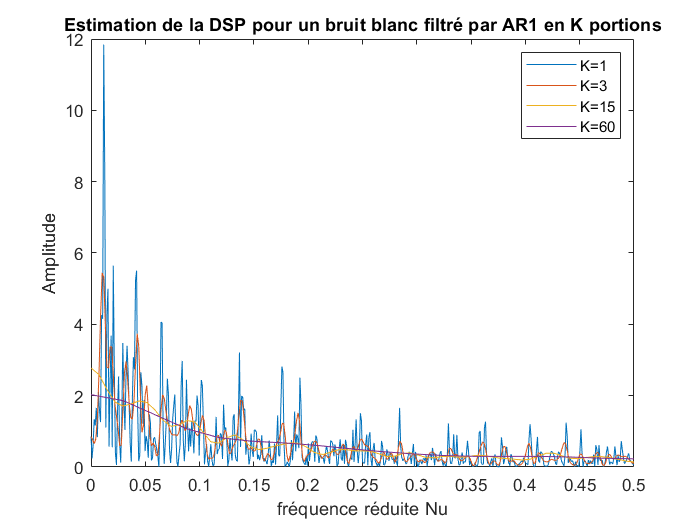

[PSDbbfiltre2, Nubbfiltre2] = psdEstimatorC2(BBfiltreParAR1);
[PSDbbfiltre3, Nubbfiltre3] = psdEstimatorC2(BBfiltreParAR1, 2048, 3);
[PSDbbfiltre4, Nubbfiltre4] = psdEstimatorC2(BBfiltreParAR1, 2048,15);
[PSDbbfiltre5, Nubbfiltre5] = psdEstimatorC2(BBfiltreParAR1, 2048,60);

plot(Nubbfiltre2, PSDbbfiltre2)
xlabel("fréquence réduite Nu")
ylabel("Amplitude")

hold on

plot(Nubbfiltre3, PSDbbfiltre3)
plot(Nubbfiltre4, PSDbbfiltre4)
plot(Nubbfiltre5, PSDbbfiltre5)
title("Estimation de la DSP pour un bruit blanc filtré par AR1 en K portions")
legend("K=1", "K=3", "K=15", "K=60");

hold off